# Transmitting and Receiving a pure Tone in ADALM-Pluto SDR

We are going to generate a pure tone using Communications Toolbox™ App Wireless Waveform Generator and transmit it and recieve it at the same time using Analog Devices ADALM-Pluto SDR.

## Tone Generation:

The SDR needs complex input values, thus the input sinusoid mut have real and imaginary parts. Rememering Eulers identity as:


$$e^{j \theta}=\cos (\theta)+j \sin (\theta)$$


A complex tone could be created by multiplying this equation by $A\geq0$ and setting $\theta = \omega t + \phi$, where here $t$ is time in seconds,  $\omega$ is radian frequency, and $\phi$ is a phase offset, we obtain what we call the *complex* [*sinusoid*](http://www.dsprelated.com/dspbooks/mdft/Sinusoids.html)*.*


$$s(t) \triangleq A e^{j(\omega t+\phi)}=A \cos (\omega t+\phi)+j A \sin (\omega t+\phi)$$


Translating this into MATLAB code:

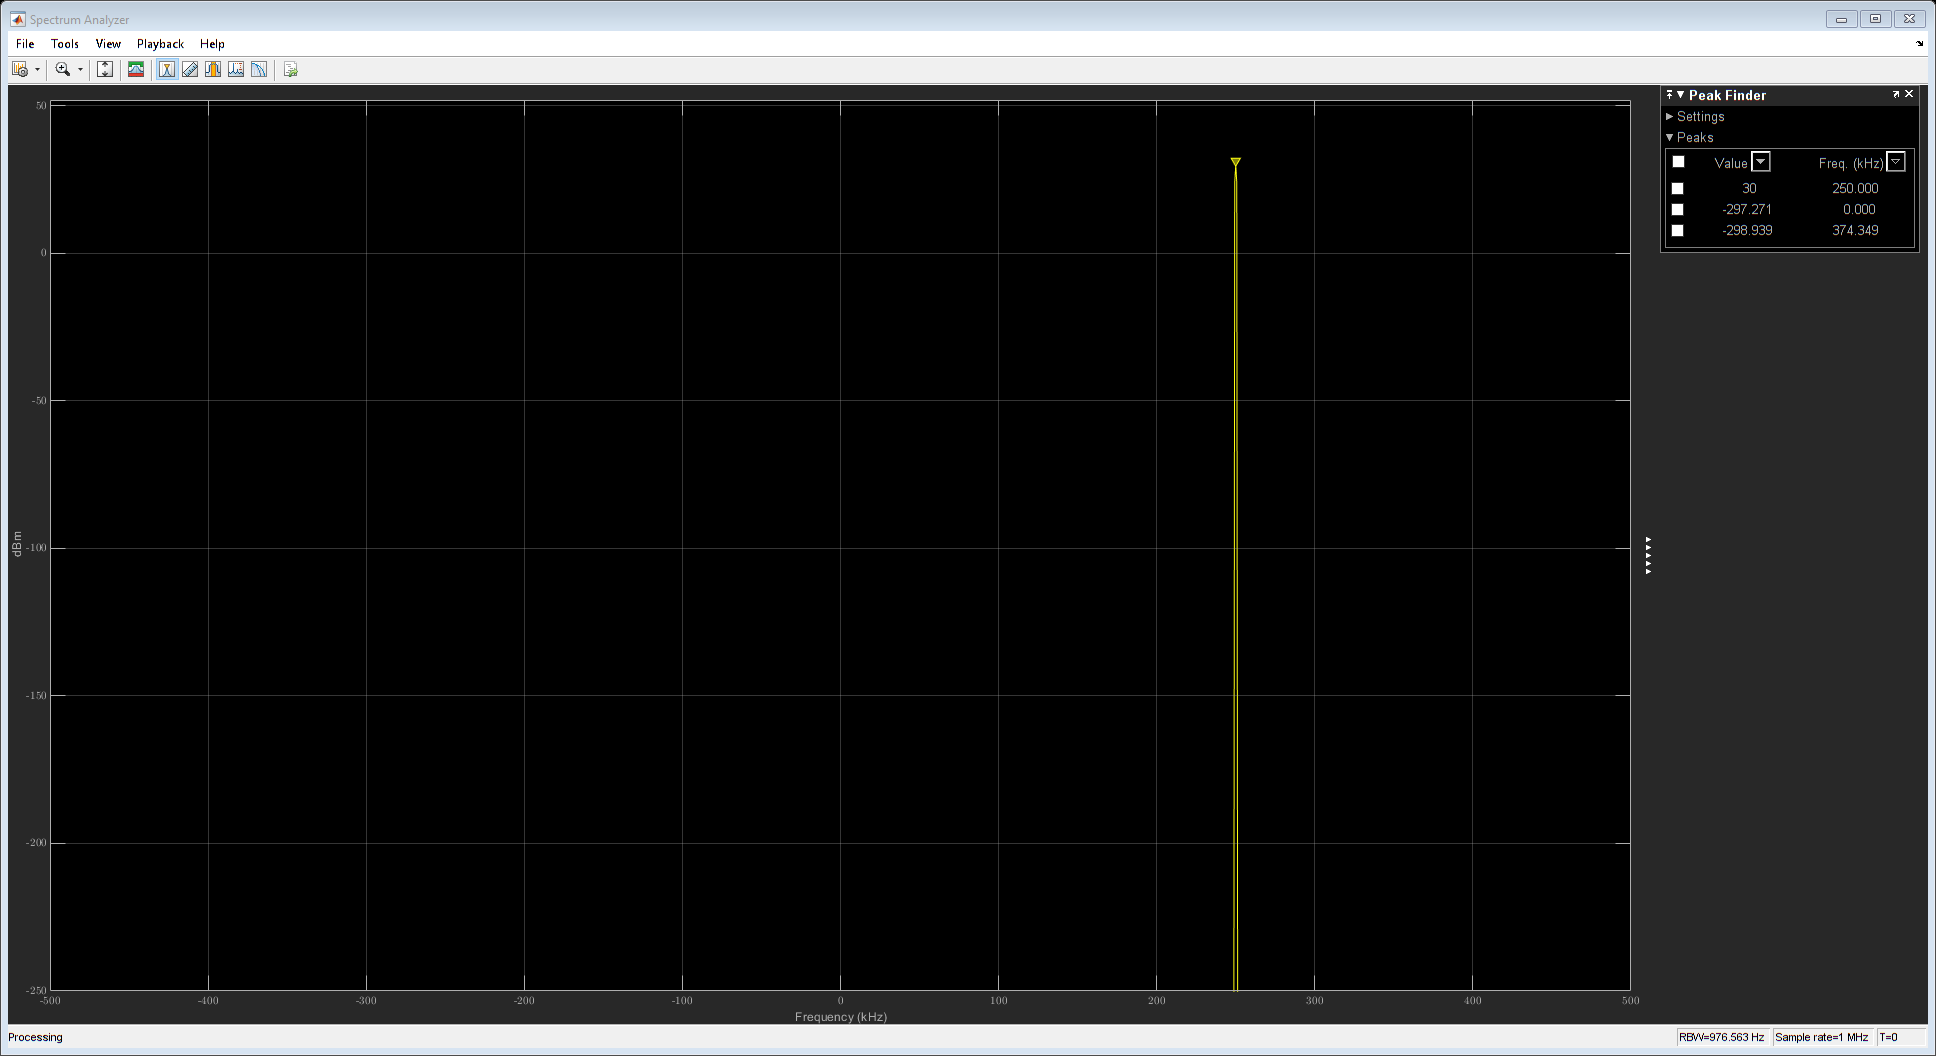

fs = 1e6;  % Specify the sample rate of the waveform in Hz
fc = 250e3; % Specify the tone frequency in Hz
% Sine Wave configuration
sineWaves = dsp.SineWave('Frequency', fc, ...
    'Amplitude', 1, ...
    'PhaseOffset', 0, ...
    'SampleRate', fs , ...
    'ComplexOutput', 1, ...
    'SamplesPerFrame', 0.01*fs);
%y = chirp(t,0,1,250, 'complex')';
% Generation
tone = sineWaves();
specAn = dsp.SpectrumAnalyzer('SampleRate', fs, ...
    'Position',[1 41 1920 963], ...
    'YLimits',[-250 52], ...
    'AxesScaling','Manual');
specAn.PeakFinder.Enable = true;
specAn(tone);

We can check our tone is correctly creted by playing its sound:

fs2 = 4e3;
sound(real(tone), 2*fs2);

## Transmitter and Receiver Configuration:

First of all we are going to instantiate Pluto SDR System Objects with deafult configuration:

tx = sdrtx("Pluto")

tx =   comm.SDRTxPluto with properties:

   Main
                DeviceName: 'Pluto'
                   RadioID: 'usb:0'
           CenterFrequency: 2.4000e+09
                      Gain: -10
            ChannelMapping: 1
        BasebandSampleRate: 1000000
    ShowAdvancedProperties: false

  Show all properties


rx =   comm.SDRRxPluto with properties:

   Main
                DeviceName: 'Pluto'
                   RadioID: 'usb:0'
           CenterFrequency: 2.4000e+09
                GainSource: 'AGC Slow Attack'
            ChannelMapping: 1
        BasebandSampleRate: 1000000
            OutputDataType: 'int16'
           SamplesPerFrame: 20000
           EnableBurstMode: false
    ShowAdvancedProperties: false

  Show all properties


## Spectrum Analyzer Configuration:

To visualize our complex tone spectrum, we are going to use Spectrum Analyzer System object™ from the DSP System Toolbox™:

specAn = dsp.SpectrumAnalyzer('SampleRate', fs, 'SpectralAverages', 40,...
    'YLimits', [0 100], 'Title', "Real-time Spectrum Visualization");
specAn.PeakFinder.Enable = true;

## Continuous Transmit and Recieve:

We are going to continously Transmit and Recive our complex tone during 20 seconds:

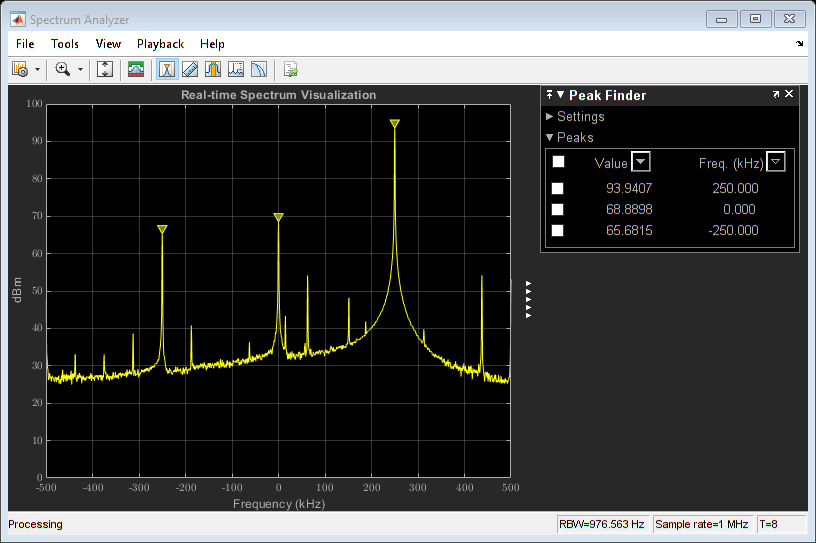

## Establishing connection to hardware. This process can take several seconds.


## Establishing connection to hardware. This process can take several seconds.


tic;
while toc<20
    rxOut = rx();
    specAn(rxOut);
    if toc>5 
        
    end
end

## Releasing Transmitter:

Anytime the Pluto SDR is powered on, the transceiver is activated and begins to operate even if the user did not intend to. To stop transmitting we execute:

release(tx);